%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 读取hdf5文件中的数据
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hopping_params_before = h5read('hopping_parameters.h5', '/hopping_parameters_before');
% 转化为meV单位
hopping_params_before = hopping_params_before * 1000;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 计算能带结构 附加 计算每个本征态的层分布
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
gamma0 = hopping_params_before(1);
gamma1 = hopping_params_before(2);
gamma2 = hopping_params_before(3);
gamma3 = hopping_params_before(4);  
gamma4 = hopping_params_before(5);
gamma5 = hopping_params_before(6);
delta = hopping_params_before(7);
Delta2 = hopping_params_before(8);

通过滑块调节Delta1参数的值

Delta1 =75; % 参考值 : 0 / 25 / 50 / 150 / 180 / 250

通过滑块调节 kmesh 的网格密度

N_kx =101;
akx_start = -0.1;
akx_end = 0.1;
akx_list = linspace(akx_start, akx_end, N_kx); % 创建akx_list

N_ky =101;
aky_start = -0.1;
aky_end = 0.1;
aky_list = linspace(aky_start, aky_end, N_ky); % 创建akx_list

参数初始化

% 存放本征值
eig_enes_K = zeros(N_ky, N_kx, 6);
eig_enes_Kp = zeros(N_ky, N_kx, 6);

% 存放本征态(虽然可能会稍微有点大) ===> 可以用来计算 宇称分布 / 层分布
eig_vecs_K = zeros(N_ky, N_kx, 6, 6);
eig_vecs_Kp = zeros(N_ky, N_kx, 6, 6);

计算 本征态 / 本征值

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 计算本征态/本征值
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1:N_kx
    akx = akx_list(i);
    for j = 1:N_ky
        aky = aky_list(j);

        [HK_m_ham, HKp_m_ham, HK_b_ham, HKp_b_ham] = ...
            construct_trilayer_ABA_six_bands_continuum_model(...
                gamma0, gamma1, gamma2, gamma3, gamma4, gamma5, ...
                delta, Delta2, akx, aky ...
            );
        if Delta1 == 0
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % K valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            [Vm_K, D] = eig(HK_m_ham);
            eig_enes_K(j, i, 1:2) = diag(D);
            eig_vecs_K(j, i, 1:2, 1:2) = Vm_K;
            [Vb_K, D] = eig(HK_b_ham);
            eig_enes_K(j, i, 3:6) = diag(D);
            eig_vecs_K(j, i, 3:6, 3:6) = Vb_K;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % Kp valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            [Vm_Kp, D] = eig(HKp_m_ham);
            eig_enes_Kp(j, i, 1:2) = diag(D);
            eig_vecs_Kp(j, i, 1:2, 1:2) = Vm_Kp;
            [Vb_Kp, D] = eig(HKp_b_ham);
            eig_enes_Kp(j, i, 3:6) = diag(D);
            eig_vecs_Kp(j, i, 3:6, 3:6) = Vb_Kp;
        else
            Delta1_mat = zeros(2, 4);
            Delta1_mat(1, 1) = Delta1;
            Delta1_mat(2, 2) = Delta1;
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % K valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            HK_ham = [HK_m_ham, Delta1_mat; Delta1_mat', HK_b_ham];
            [V_K, D] = eig(HK_ham);
            eig_enes_K(j, i, :) = diag(D);
            eig_vecs_K(j, i, :, :) = V_K;
            
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % Kp valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            HKp_ham = [HKp_m_ham, Delta1_mat; Delta1_mat', HKp_b_ham];
            [V_Kp, D] = eig(HKp_ham);
            eig_enes_Kp(j, i, :) = diag(D);
            eig_vecs_Kp(j, i, :, :) = V_Kp;
        end

    end
end

通过 本征态 计算 宇称分布 以及 层分布

% 颜色
red_RGB = [1 0 0]; % 红色对应单层
green_RGB = [0 1 0];
blue_RGB = [0 0 1]; % 蓝色对应双层
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 每个本征态对应的宇称成分
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
eig_parity_K = zeros(N_ky, N_kx, 6, 3);
eig_parity_Kp = zeros(N_ky, N_kx, 6, 3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 每个本征态对应的层分布
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
eig_layer_K = zeros(N_ky, N_kx, 6, 3);
eig_layer_Kp = zeros(N_ky, N_kx, 6, 3);

for i = 1:N_kx
    for j = 1:N_ky
        V_K = squeeze(eig_vecs_K(j, i, :, :));
        V_Kp = squeeze(eig_vecs_Kp(j, i, :, :));
        if Delta1 == 0
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % K valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % calculate parity
            eig_parity_K(j, i, 1:2, :) = [red_RGB; red_RGB];
            eig_parity_K(j, i, 3:6, :) = [blue_RGB; blue_RGB; blue_RGB; blue_RGB];
            
            % calculate layer distribution
            V_K = [Vm_K, zeros(2,4);zeros(4,2), Vb_K];
            % layer 1 sites
            prob_K_layer1_mat = transpose(V_K) * [1, 0; 0, 1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            % layer 2 sites
            prob_K_layer2_mat = transpose(V_K) * [0, 0; 0, 0; 0, 0; 0, 0; 1, 0; 0, 1];
            % layer 3 sites
            prob_K_layer3_mat = transpose(V_K) * [-1, 0; 0, -1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            
            % 存入矩阵中
            for k = 1:6
                % layer 1
                eig_layer_K(j, i, k, 1) = (abs(prob_K_layer1_mat(k, 1)))^2 + (abs(prob_K_layer1_mat(k, 2)))^2;
                % layer 2
                eig_layer_K(j, i, k, 2) = (abs(prob_K_layer2_mat(k, 1)))^2 + (abs(prob_K_layer2_mat(k, 2)))^2;
                % layer 3
                eig_layer_K(j, i, k, 3) = (abs(prob_K_layer3_mat(k, 1)))^2 + (abs(prob_K_layer3_mat(k, 2)))^2;
            end
            
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % Kp valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % calculate parity
            eig_parity_Kp(j, i, 1:2, :) = [red_RGB; red_RGB];
            eig_parity_Kp(j, i, 3:6, :) = [blue_RGB; blue_RGB; blue_RGB; blue_RGB];
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % calculate layer distribution
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            V_Kp = [Vm_Kp, zeros(2,4);zeros(4,2), Vb_Kp];
            % layer 1 sites
            prob_Kp_layer1_mat = transpose(V_Kp) * [1, 0; 0, 1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            
            % layer 2 sites
            prob_Kp_layer2_mat = transpose(V_Kp) * [0, 0; 0, 0; 0, 0; 0, 0; 1, 0; 0, 1];
            
            % layer 3 sites
            prob_Kp_layer3_mat = transpose(V_Kp) * [-1, 0; 0, -1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            
            % 存入矩阵中
            for k = 1:6
                % layer 1
                eig_layer_Kp(j, i, k, 1) = (abs(prob_Kp_layer1_mat(k, 1)))^2 + (abs(prob_Kp_layer1_mat(k, 2)))^2;
                % layer 2
                eig_layer_Kp(j, i, k, 2) = (abs(prob_Kp_layer2_mat(k, 1)))^2 + (abs(prob_Kp_layer2_mat(k, 2)))^2;
                % layer 3
                eig_layer_Kp(j, i, k, 3) = (abs(prob_Kp_layer3_mat(k, 1)))^2 + (abs(prob_Kp_layer3_mat(k, 2)))^2;
            end
        else
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % K valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % calculate parity
            for k = 1:6
                red_weight = sum(abs(V_K(1:2, k)).^2);
                blue_weight = sum(abs(V_K(3:6, k)).^2);
                eig_parity_K(j, i, k, :) = red_RGB * red_weight + blue_RGB * blue_weight;
            end
            
            % calculate layer distribution
            % layer 1 sites
            prob_K_layer1_mat = transpose(V_K) * [1, 0; 0, 1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            % layer 2 sites
            prob_K_layer2_mat = transpose(V_K) * [0, 0; 0, 0; 0, 0; 0, 0; 1, 0; 0, 1];
            % layer 3 sites
            prob_K_layer3_mat = transpose(V_K) * [-1, 0; 0, -1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            
            % 存入矩阵中
            for k = 1:6
                % layer 1
                eig_layer_K(j, i, k, 1) = (abs(prob_K_layer1_mat(k, 1)))^2 + (abs(prob_K_layer1_mat(k, 2)))^2;
                % layer 2
                eig_layer_K(j, i, k, 2) = (abs(prob_K_layer2_mat(k, 1)))^2 + (abs(prob_K_layer2_mat(k, 2)))^2;
                % layer 3
                eig_layer_K(j, i, k, 3) = (abs(prob_K_layer3_mat(k, 1)))^2 + (abs(prob_K_layer3_mat(k, 2)))^2;
            end
            
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % Kp valley 的计算
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % calculate parity
            for k = 1:6
                red_weight = sum(abs(V_Kp(1:2, k)).^2);
                blue_weight = sum(abs(V_Kp(3:6, k)).^2);
                eig_parity_Kp(j, i, k, :) = red_RGB * red_weight + blue_RGB * blue_weight;
            end
            
            % calculate layer distribution
            % layer 1 sites
            prob_Kp_layer1_mat = transpose(V_Kp) * [1, 0; 0, 1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            % layer 2 sites
            prob_Kp_layer2_mat = transpose(V_Kp) * [0, 0; 0, 0; 0, 0; 0, 0; 1, 0; 0, 1];
            % layer 3 sites
            prob_Kp_layer3_mat = transpose(V_Kp) * [-1, 0; 0, -1; 1, 0; 0, 1; 0, 0; 0, 0] * 1 / sqrt(2);
            
            % 存入矩阵中
            for k = 1:6
                % layer 1
                eig_layer_Kp(j, i, k, 1) = (abs(prob_Kp_layer1_mat(k, 1)))^2 + (abs(prob_Kp_layer1_mat(k, 2)))^2;
                % layer 2
                eig_layer_Kp(j, i, k, 2) = (abs(prob_Kp_layer2_mat(k, 1)))^2 + (abs(prob_Kp_layer2_mat(k, 2)))^2;
                % layer 3
                eig_layer_Kp(j, i, k, 3) = (abs(prob_Kp_layer3_mat(k, 1)))^2 + (abs(prob_Kp_layer3_mat(k, 2)))^2;
            end
        end
    end
end

开始作图(可视化) :  三维曲面(只画双层) & 等高线图(只画双层)

第一部分 : K谷空穴部分

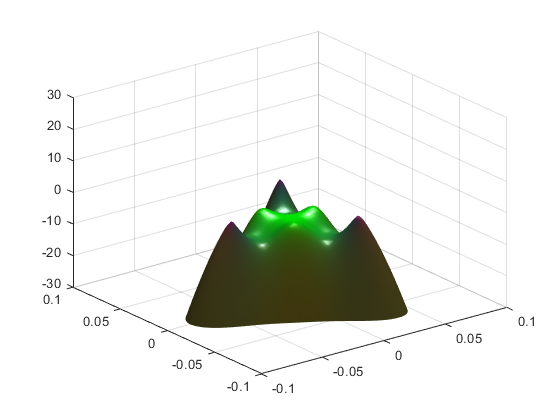

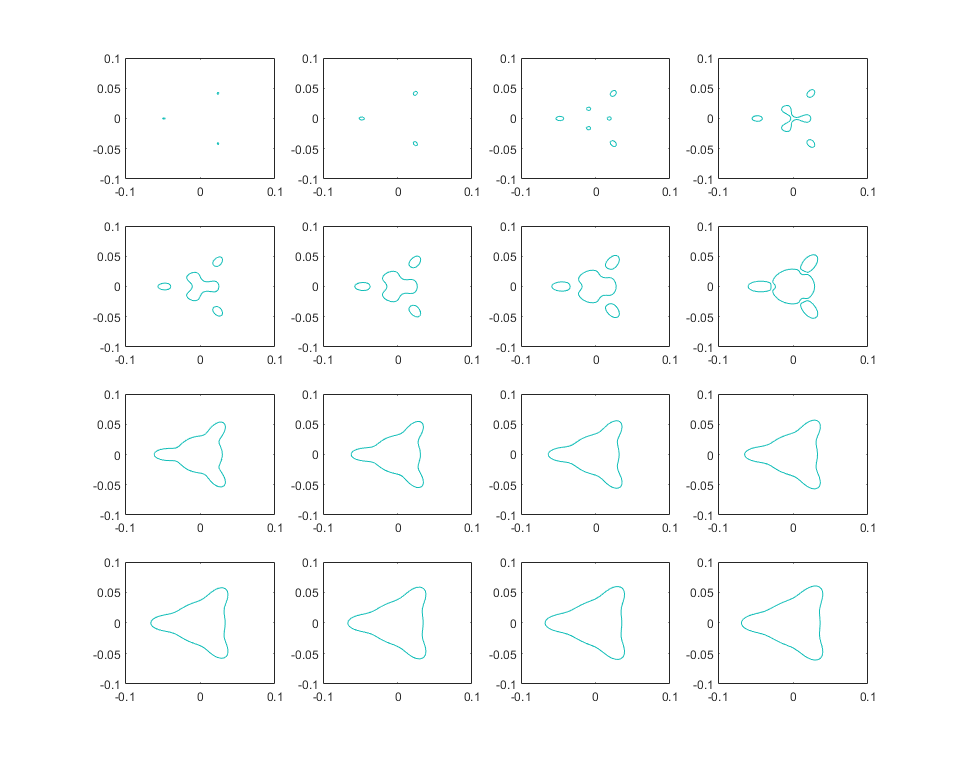

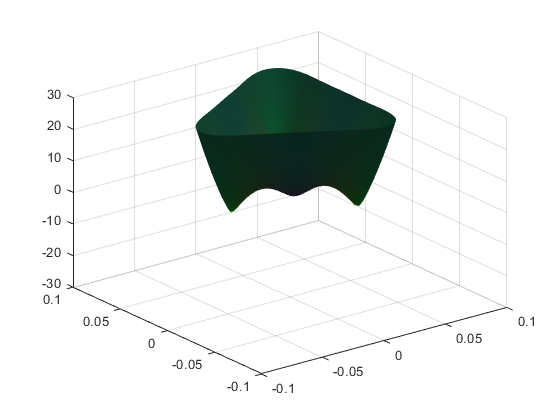

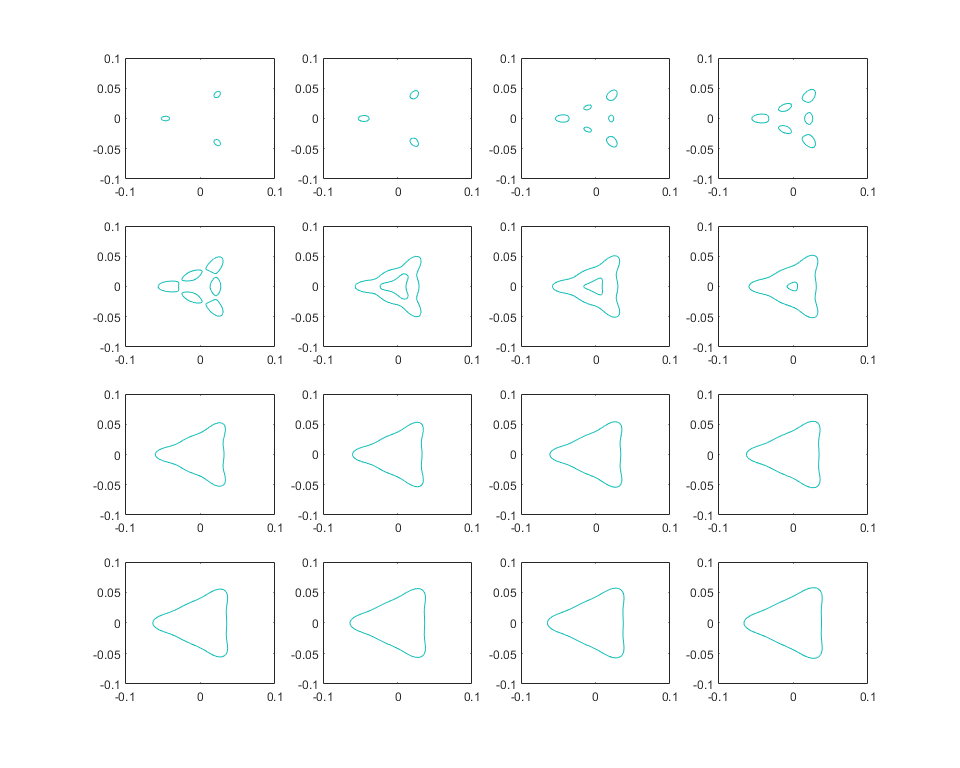

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% K valley hole side 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 三维图 (仅包含双层)
eig_index = 3;
figure
set(gca,'FontName','Times New Roman','FontSize',7);
[akx_mesh, aky_mesh] = meshgrid(akx_list, aky_list);

surf(akx_mesh, aky_mesh, eig_enes_K(:,:,eig_index), squeeze(eig_layer_K(:,:,eig_index,:)), 'FaceAlpha',1, 'EdgeColor', 'interp');
hold on
shading interp % 去掉曲面上的网格
camlight % 添加光照，使得曲面更立体
lighting phong % 哑光效果，去除表面“纹路”
zlim([-30, 30]);

% find gully points
[hole_peak_value_list, hole_peak_location_list] = find_lcm_matrix(squeeze(eig_enes_K(:,:,eig_index)));
hole_Nx = 4;
hole_Ny = 4;
hole_ene_delta = 1; % 1meV的能量间隔
hole_ene_start = -1.5;
hole_ene_level_list = zeros(1, hole_Nx * hole_Ny);
for i = 1:hole_Nx * hole_Ny
    hole_ene_level_list(i) = hole_ene_start - (i - 1) * hole_ene_delta;
end

% 等高线 (仅包含双层)
figure
set(gcf, 'unit', 'inch', 'position', [10, 5, 10.00, 8.00]) % figure
for i = 1:hole_Nx * hole_Ny
    subplot(hole_Nx, hole_Ny, i)
    % contour(akx_list, aky_list, eig_enes_K(:,:,i), "ShowText",true, 'LevelList', ene_level_list(i))
    contour(akx_list, aky_list, eig_enes_K(:,:,eig_index), 'LevelList', hole_ene_level_list(i))
end

第二部分 : K谷电子部分

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% K valley electron side 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 三维图 (仅包含双层)
eig_index = 4;
figure
set(gca,'FontName','Times New Roman','FontSize',7);
[akx_mesh, aky_mesh] = meshgrid(akx_list, aky_list);
surf(akx_mesh, aky_mesh, eig_enes_K(:,:,eig_index), squeeze(eig_layer_K(:,:,eig_index,:)), 'FaceAlpha',1, 'EdgeColor', 'interp');
shading interp % 去掉曲面上的网格
camlight % 添加光照，使得曲面更立体
lighting phong % 哑光效果，去除表面“纹路”
zlim([-30, 30]);
view(3)

% 等高线 (仅包含双层)
[ele_peak_value_list, ele_peak_location_list] = find_lcm_matrix(squeeze(-eig_enes_K(:,:,eig_index)));
ele_peak_value_list = - ele_peak_value_list;
ele_Nx = 4;
ele_Ny = 4;
ele_ene_delta = 1; % 1meV的能量间隔
ele_ene_start = 4.5;
ele_ene_level_list = zeros(1, hole_Nx * hole_Ny);
for i = 1:ele_Nx * ele_Ny
    ele_ene_level_list(i) = ele_ene_start + (i - 1) * ele_ene_delta;
end
figure
set(gcf, 'unit', 'inch', 'position', [10, 5, 10.00, 8.00]) % figure
for i = 1:ele_Nx * ele_Ny
    subplot(ele_Nx, ele_Ny, i)
    % contour(akx_list, aky_list, eig_enes_K(:,:,i), "ShowText",true, 'LevelList', ene_level_list(i))
    contour(akx_list, aky_list, eig_enes_K(:,:,eig_index), 'LevelList', ele_ene_level_list(i))
end